Loading dataset

files = dir();
file_names = {files.name}

file_names = 1×23 cell array
    {'.'}    {'..'}    {'.git'}    {'.gitattributes'}    {'.gitignore'}    {'.ipynb_checkpoints'}    {'CNN'}    {'CNN_RozpoznavanieHub.pdf'}    {'CNN_Template.ipynb'}    {'CNN_Template_MatLab.m'}    {'CNN_Template_MatLab.mlx'}    {'CNN_Training_Graph.ipynb'}    {'Clanky'}    {'Dataset_Construction_Isolated.ipynb'}    {'FinalTrainTestSet'}    {'FinalTrainTestSet.zip'}    {'Mushroom dataset'}    {'Mushroom dataset.zip'}    {'README.md'}    {'Testing'}    {'logs'}    {'mushroom_dataset_x.npy'}    {'mushroom_dataset_y.npy'}



if any(file_names(:) == "Mushroom dataset") == 0
    disp("Dataset file not found, unzipping...")
    unzip("Mushroom dataset.zip", "Mushroom dataset/")
    disp("Done")
else
    disp("Dataset file found")
end

Dataset file found



src_folder = "Mushroom dataset/cnn"

src_folder = "Mushroom dataset/cnn"

dataset = imageDatastore(src_folder, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

classNames = categories(dataset.Labels)

classNames = 2×1 cell array
    {'Edible'   }
    {'Poisonous'}


numClasses = numel(classNames)

numClasses = 2


[dataset_train, dataset_val] = splitEachLabel(dataset,0.9, 0.1, "randomized");

Train network

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:05        0.001                           0.90214                                        57
            1        1       00:00:07        0.001          1.6055            0.5938                52.5                    74
            2        1       00:00:16        0.001         0.91334           0.74068                  75                  77.5
            3        1       00:00:20        0.001         0.82525           0.59859                77.5                    80
            4        1       00:00:25        0.001         0.91883            0.4979                72.5                  79.5
            5        1       00:00:29        0.001           1.104           0.36204                  70       

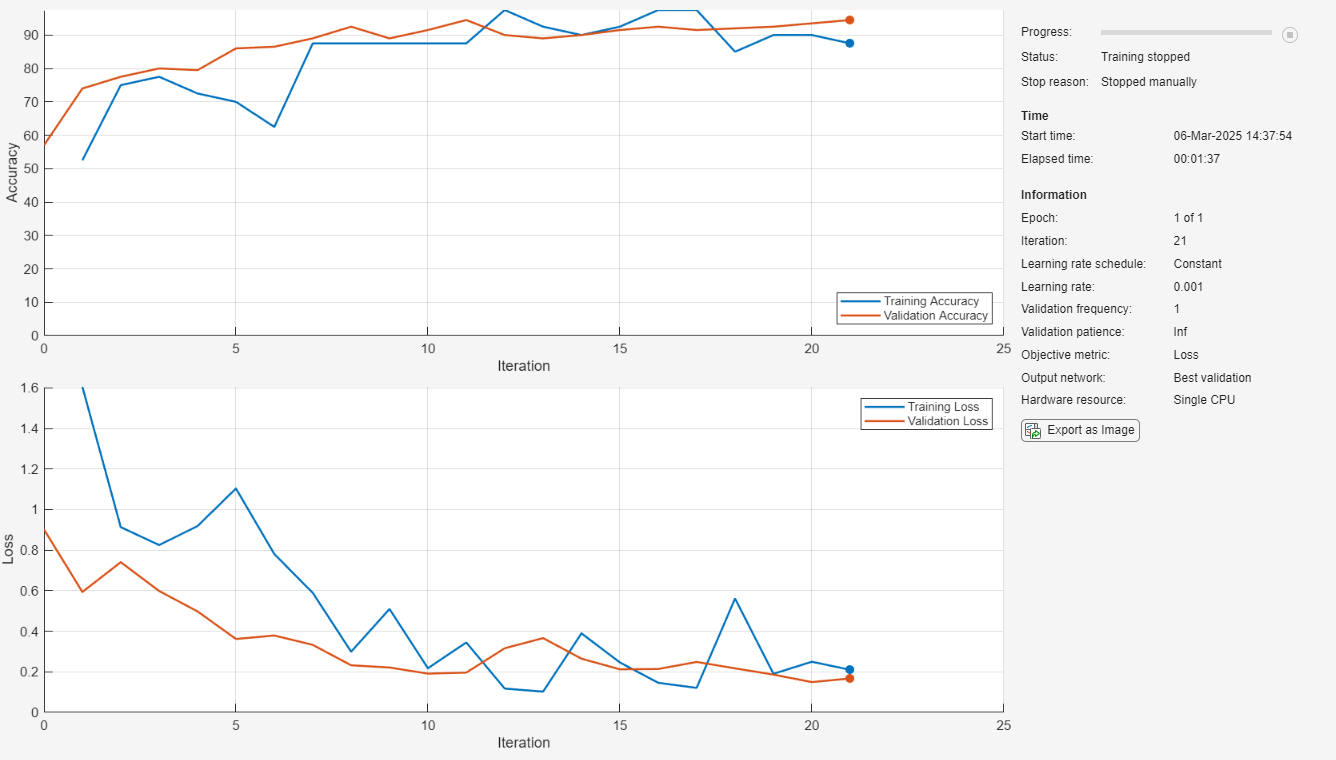

net = imagePretrainedNetwork("alexnet", NumClasses=numClasses);

options = trainingOptions("sgdm", ...
    MiniBatchSize=40, ...
    MaxEpochs=1, ...
    Metrics="accuracy", ...
    InitialLearnRate=1e-3, ...
    ValidationFrequency=1, ...
    ValidationData=dataset_val, ...
    Plots="training-progress");


[net, info]= trainnet(dataset_train, net, "crossentropy", options);